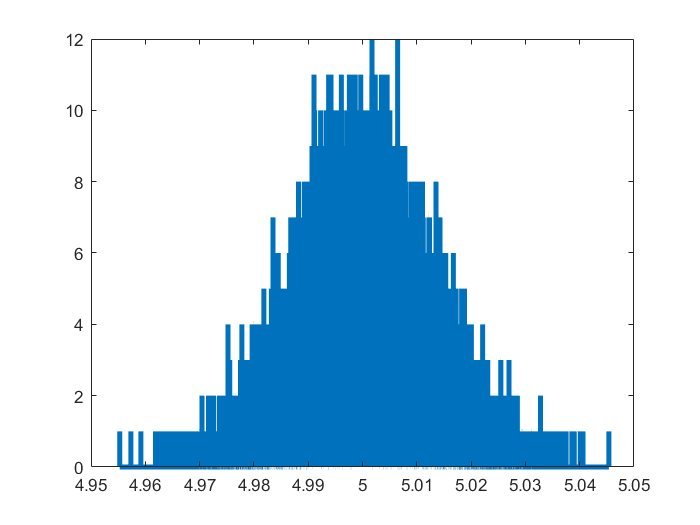

d = random('Normal', 5., 0.01, [1,100000]);
histogram(d,100000,'DisplayStyle',"stairs",'LineWidth',3)
xlim([4.95,5.05])


% 1B: for a given z value, returns the associated probability of the
% Gaussian 
n = normcdf(-1.6) % returns the appropriate probability associated with z = -1.6

n = 0.0548

n = normcdf(0) % returns the appropriate probability associated with z = 0

n = 0.5000

n = normcdf(1.6) % returns the appropriate probability associated with z = 1.6

n = 0.9452

n = 1-normcdf(5) % Complimentary value calculated to avoid rounding error

n = 2.8665e-07


% 1C
% Outputs z value associated with the standard normal probability input. Z
% values are checked against a z-table for validity
norminv(.8413) %approximately a sigma value of 1

ans = 0.9998

norminv(0.9772) %approximately a sigma value of 2

ans = 1.9991

norminv(.9999998) %approximately a sigma value of 5

ans = 5.0690


%1D The minus sign that appears indicates that the probability is to the
%left of the mean. To deal with it, the sigma value generated must be
%subtracted from 0.5, where the sigma value is zero.

% 2
x = linspace(0,10,100000);
rayl = makedist("Rayleigh",'b',3.4);

% Probability Distribution of Rayleigh Distribution
subplot(2,2,2)
plot(x,pdf(rayl,x),"LineWidth",4);
set(gca,'YScale','log')

% Rayleigh Distribution
subplot(2,2,1)
plot(x,pdf(rayl,x),"LineWidth",4);

x = linspace(0,40,100000);    
chisq = makedist("Gamma",'a',18/2.,'b',2.); %special case for Chi-squared

%Probability Distribution of a Chi-Squared Distribution
subplot(2,2,4)
plot(x,pdf(chisq,x),"LineWidth",4);
set(gca,'YScale','log')

%Chi-Squared Distribution
subplot(2,2,3)
plot(x,pdf(chisq,x),"LineWidth",4);

%3A Rayleigh distribution above, value of 9.95

%3B Question - If there is no signal, and the signal-free data has a
%Rayleigh distribution, what is the probability that the data produced a
%signal that is equally or more signal-like than I observed for a threshold of 9.95?

%3C Integral of the probability distribution function of the Rayleighan
%distribution from 9.95 to infinity.


$$\int_{9\ldotp 95}^{\infty } \left(\frac{r}{s^2 }\right)*e^{\frac{\left(-r^2 \right)}{\left(2s^2 \right)}}$$



%3D
y = cdf(rayl,9.95)

y = 0.9862


%3E sigma value associated with a threshold of 9.95 in the above
%distribution 'rayl'
norminv(y)

ans = 2.2025

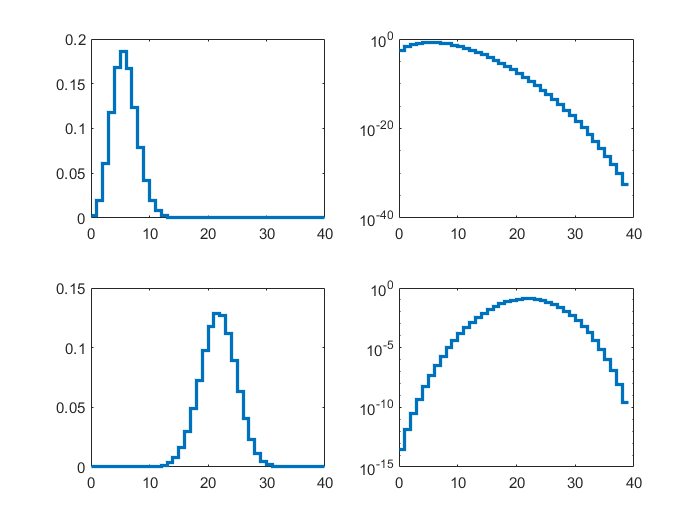


% Non-continuous Distribution

%1A


x = 0:40;
bin = makedist("Binomial",'N',38, 'p',0.14); 
subplot(2,2,2)
stairs(x,pdf(bin,x),"LineWidth",2);
set(gca,'YScale','log')
subplot(2,2,1)
stairs(x,pdf(bin,x),"LineWidth",2);

%Probability of success (p) changed to a value 4 times that of the last
%simulation. The number of trials held is the same. This induces a
%pronounced shift to the right, recentering the binomial distribution to
%0.56 of the x-axis.
bin = makedist("Binomial",'N',38, 'p',0.56); 
subplot(2,2,4)
stairs(x,pdf(bin,x),"LineWidth",2);
set(gca,'YScale','log')
subplot(2,2,3)
stairs(x,pdf(bin,x),"LineWidth",2);


%C If there is no signal, and the signal-free data has a
%Binomial distribution, what is the probability that the data produced a
%signal that is equally or more signal-like than I observed for a threshold of 30?
y = cdf(bin,30)

y = 0.9991


%sigma value associated with a threshold of 30
norminv(y)

ans = 3.1367


%D
%Since the probabilities and sigmas are also discrete due to the nature of
%the data set, an added layer of confidence may be introduced since
%anything which is not a discrete value may immediately be discarded if the
%experiment is sufficiently understood. The experiment should also have
%easily calculable values for the distribution probabilities and associated
%sigmas.

%E
% For non-continuous distributions, most parameters affect the totality of
% the data set, not just the discrete values. For example, the average is
% a weighted metric. As such, it won't have a discrete value most likely
% (it may, but characteristically it won't take a nice value as the
% discrete quantities). Continuous distributions should generally lead to
% smoother data sets as all values within a defined range may be
% represented. The mean will generally be less affected by outliers since
% most of the data will be about the expected value if the experiment was
% well designed.